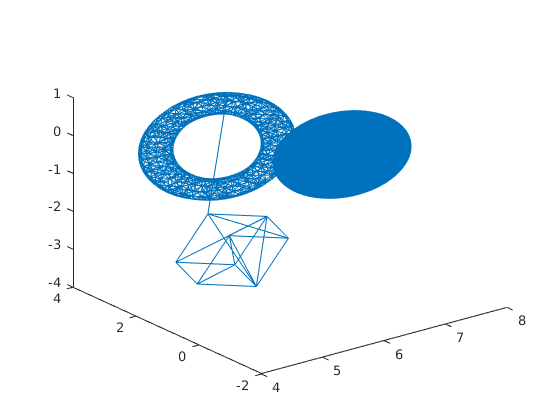

A = dlmread('Documents/learning/parallel_programming/tracer/src/model.xyz');
plot3(A(:,1),A(:,2),A(:,3));

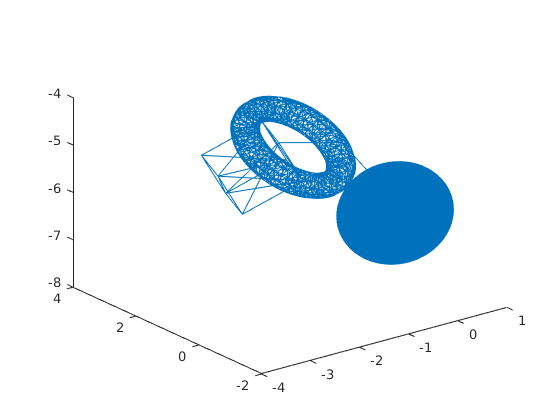

[X, Y, Z] = rotY(A(:,1),A(:,2),A(:,3), pi/2);
plot3(X, Y, Z);

A(:,1) = X, A(:,2) = Y ,A(:,3) = Z;

A =    -1.4643    1.4134   -1.4643
   -1.4752    0.6242   -1.4752
   -2.4496    1.0329   -2.4496
   -2.4388    1.8221   -2.4388
   -2.4496    1.0329   -2.4496
   -3.1519    0.4672   -3.1519
   -3.1410    1.2564   -3.1410
   -3.1519    0.4672   -3.1519
   -2.1775    0.0585   -2.1775
   -2.1666    0.8478   -2.1666


A =    -1.4643    1.4134   -1.4643
   -1.4752    0.6242   -1.4752
   -2.4496    1.0329   -2.4496
   -2.4388    1.8221   -2.4388
   -2.4496    1.0329   -2.4496
   -3.1519    0.4672   -3.1519
   -3.1410    1.2564   -3.1410
   -3.1519    0.4672   -3.1519
   -2.1775    0.0585   -2.1775
   -2.1666    0.8478   -2.1666


writematrix(A,'Documents/learning/parallel_programming/tracer/src/model_rotated.txt','Delimiter','space');

function [X, Y, Z] = rotX(x,y,z,theta)
    X = x;
    Y = y*cos(theta) - z*sin(theta);
    Z = y*sin(theta) + z*cos(theta);
end
function [X, Y, Z] = rotY(x,y,z,theta)
    X = x*cos(theta) + z*sin(theta);
    Y = y;
    Z = z*cos(theta) - x*sin(theta);
end
function [X, Y, Z] = rotZ(x,y,z,theta)
    X = x*cos(theta) - y*sin(theta);
    Y = x*sin(theta) + y*cos(theta);
    Z = z;
end